format long
f=@(x)(((ln(x)-1+x)/(ln(x)+((1-x)/((5/3)-1)))-0.3))
aprox1=abs(f(4.6))
syms x
df=diff(f(x));
dfu=matlabFunction(df);
z=4.1445;
error=1;
Tol=1e-5;
n = 0;
while error>Tol
    x1=x0-f(x0)/dfu(x0);
    z=[z;x1];
    error=abs(x1-x0)/abs(x1);
    x0=x1;
    n= n+1
end
coc1=x0
totaliter= n


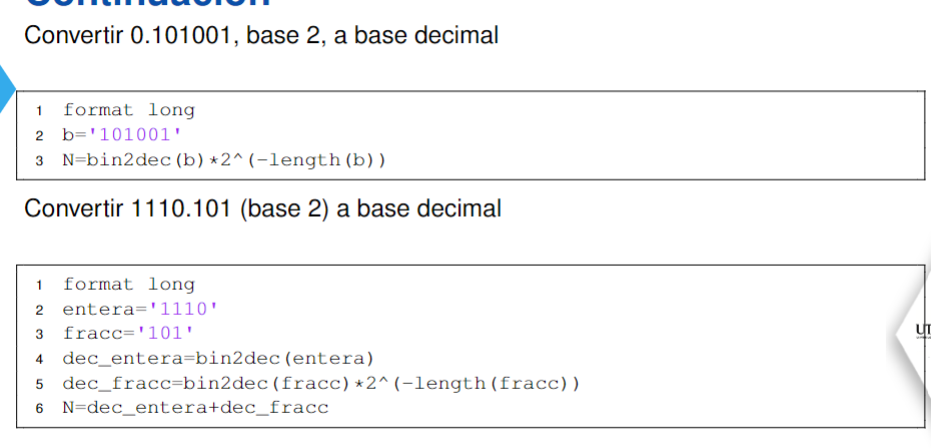

Punto flotante, ejemplo:

b='10111110011000000000000000000000';
s=b(1)
e=b(2:9)
m=b(10:32)
dec_s=bin2dec(s)
dec_e=bin2dec(e)
dec_m=bin2dec(m)*2^(-length(m))
x=(-1)^dec_s*2^(dec_e-127)*(1+dec_m)

Redondeado

function y=redond(x,n)
%Devuelve x redondeado a n cifras significativas.
if x==0
    y=0;
else
    s=sign(x);
    expo=ceil(log(abs(x))/log(10));
    mant=exp(log(abs(x))-expo*log(10));
    nm=round(mant*10^n)/(10^n);
    y=s*nm*10^expo;
end
end

Ecuaciones cuadráticas

function [x1,x2]=cuadratica(a,b,c,n)
x1=div(suma(-b,raiz(resta(prod(b,b,n),4*prod(a,c,n),n),n),n),...
prod(2,a,n),n);
x2=div(resta(-b,raiz(resta(prod(b,b,n),4*prod(a,c,n),n),n),n),...
prod(2,a,n),n);
end

Punto fijo

function z=pfijo(g,x0,Maxiter)
z=[x0];
for k=1:Maxiter
    x1=g(x0);
    z=[z;x1];
    x0=x1;
end
end

Teorema de Balzano

%f=@(x)(-x^2+2*x+exp(x))
a=-1
b=0
if f(a)*f(b)<0
    fprintf('Existe al menos una raiz')
else
    fprintf('No se puede afirmar que existe una raiz')
end

syms x y
F=@(x,y)([2*x-y-exp(-x);-x+2*y-exp(-y)])
dF=jacobian(F(x,y),[x,y])
dFfun=double(subs(dF,{x,y},{3,4}))
%jacobiano evaluado en (3,4)

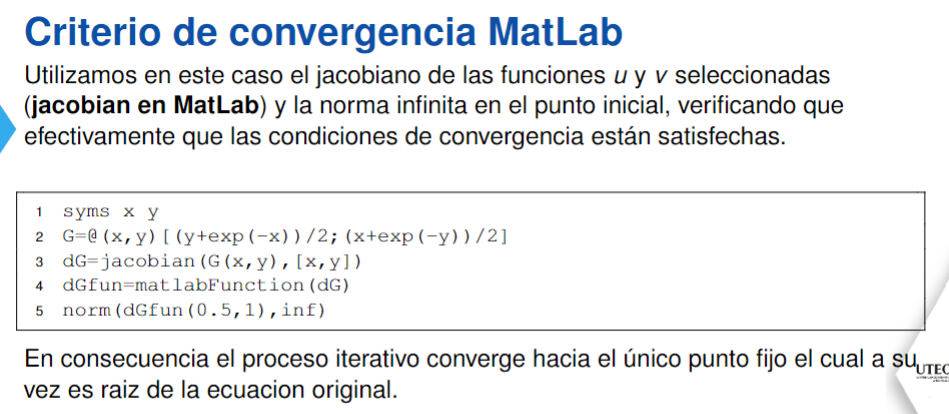

Newton tolerancia

function z=newton(f,x0,Tol)
syms x
df=diff(f(x));
dfu=matlabFunction(df);
z=x0;
error=1;
while error>Tol
    x1=x0-f(x0)/dfu(x0);
    z=[z;x1];
    error=abs(x1-x0)/abs(x1);
    x0=x1;
end
end

Bisección tolerancia 

function z=biseccion2(f,a,b,Tol)
c=(a+b)/2;
error=(b-a)/2;
z=[a b c f(a) f(b) f(c) error];
N=ceil(log((b-a)/(2*Tol))/log(2));
fprintf('Se necesita %d iteraciones\n',N)
while error>Tol
    if f(a)*f(c)<0
        b=c;
    else
        a=c;
    end
    c=(a+b)/2;
    error=(b-a)/2;
    z=[z; a b c f(a) f(b) f(c) error];
end
end


Bisección máximo iteraciones

function z=biseccion(f,a,b,Maxiter)

c=(a+b)/2;
error=(b-a)/2;
z=[a b c f(a) f(b) f(c) error];
for k=1:Maxiter
    if f(a)*f(c)<0
        b=c;
    else
        a=c;
    end
    c=(a+b)/2;
    error=(b-a)/2;
    z=[z;a b c f(a) f(b) f(c) error];
end
end
